Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Image and Video Processing Tutorial - 5**

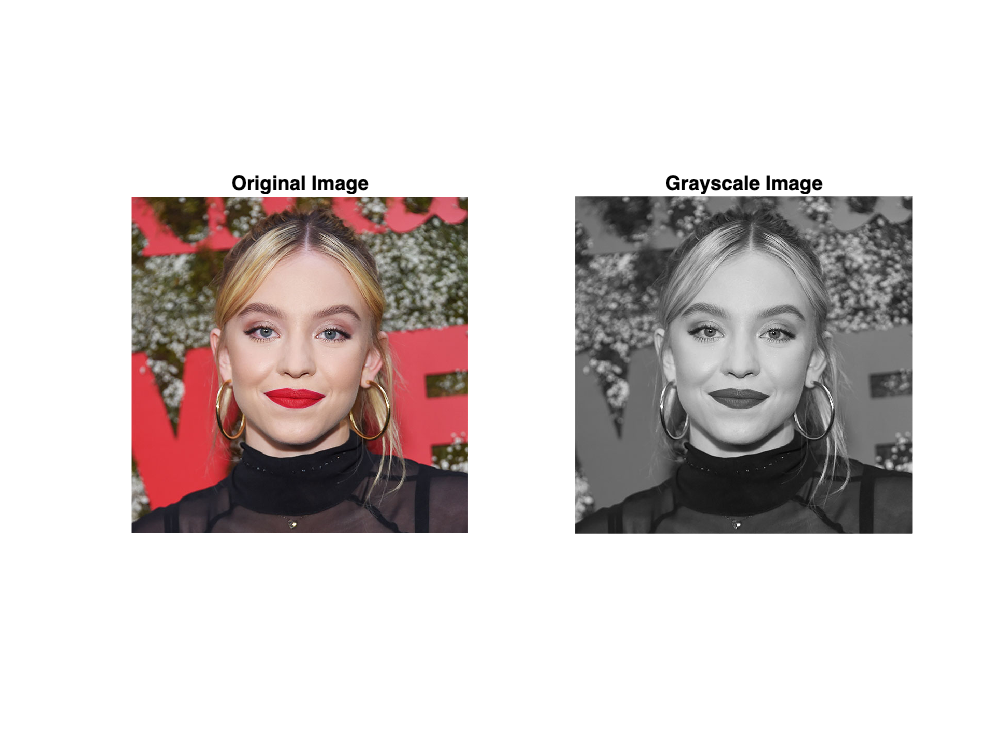

% To read test image and inputs in a matrix form
input_image  = imread('./assets/tut4-img.jpg');
% Convert to grayscale
img = rgb2gray(input_image);

figure;
subplot(1, 2, 1);
imshow(input_image);
title("Original Image");
subplot(1, 2, 2);
imshow(img);
title("Grayscale Image");

### Motion Blur Filter

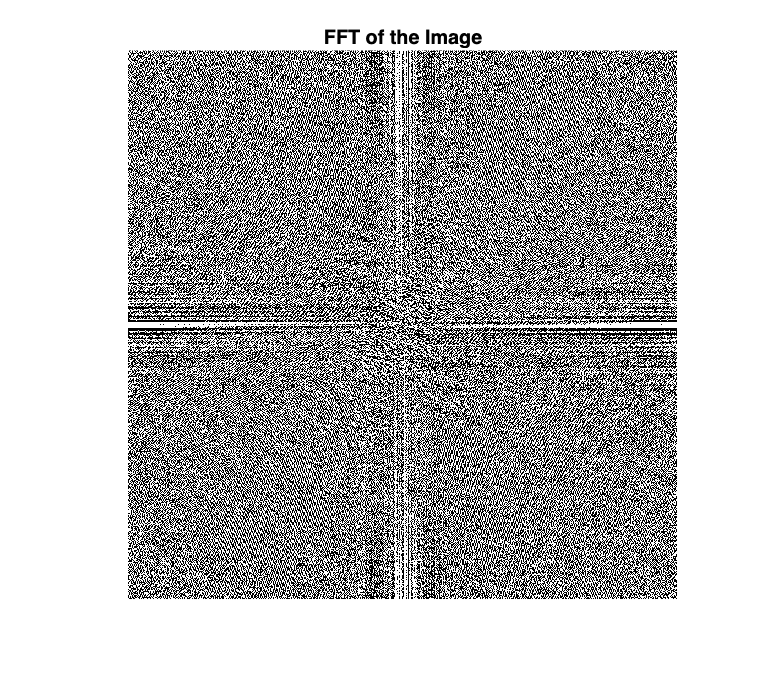

% Convert to frequency domain
c_img = center(cast(img, 'double'));
f_img = fft2(c_img);
figure;
imshow(real(f_img));
set(gca,'OuterPosition',[0 0 1 1]);
title("FFT of the Image");

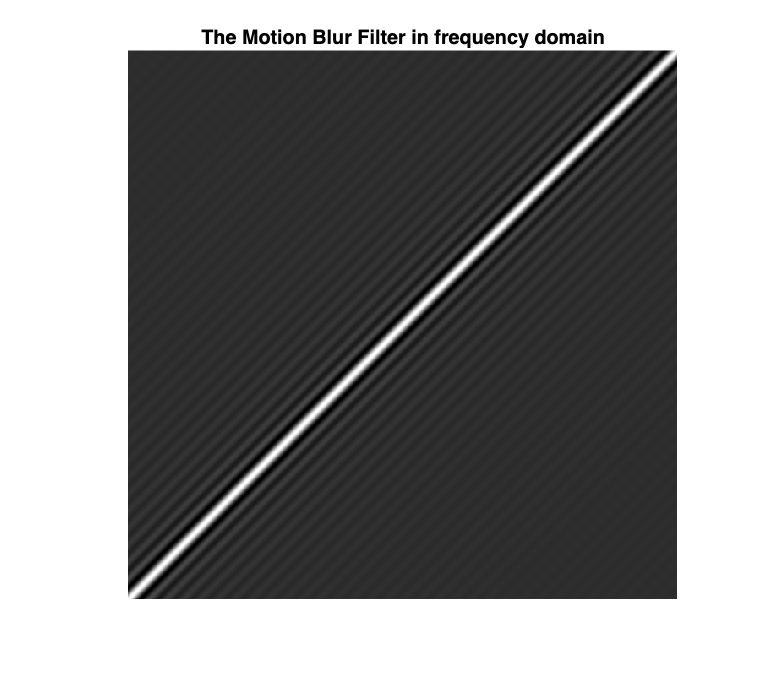

% Applying the motion blur filter
filter = getMotionBlurFilter(size(img, 1), size(img, 2), 0.05, 0.05, 0.3);
figure;
imshow(real(filter),[]);
set(gca,'OuterPosition',[0 0 1 1]);
title("The Motion Blur Filter in frequency domain");

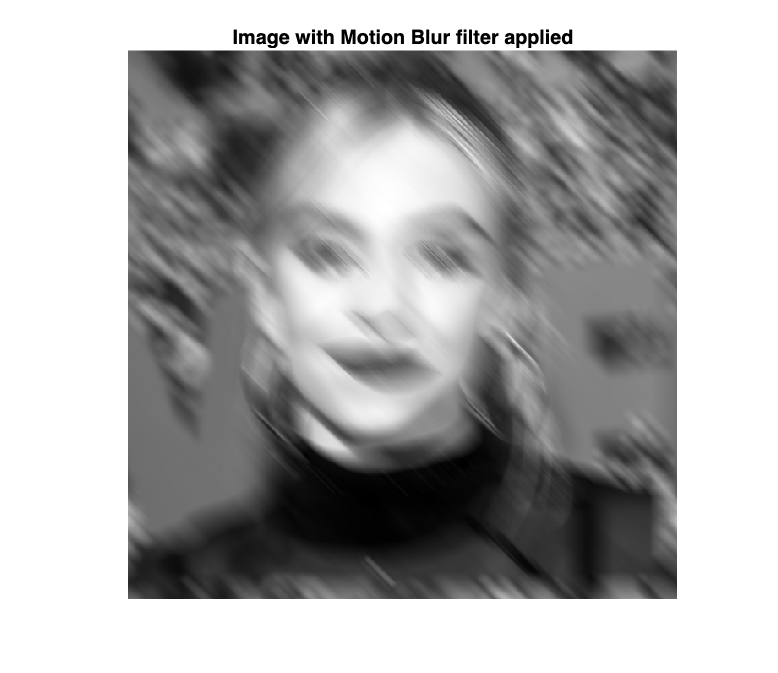

% Applying the filter
f_filtered = f_img .* filter;
filtered = center(real(ifft2(f_filtered)));
figure;
imshow(filtered,[]);
set(gca,'OuterPosition',[0 0 1 1]);
title("Image with Motion Blur filter applied");

function filter = getMotionBlurFilter(n, m, a, b, T)
    % Create the motion blur filter
    filter = zeros(n, m);
    for i = 1:n
        for j = 1:m
            M = n/2 - i + 1;
            N = m/2 - j + 1;
            k = (M * a) + (N * b);
            filter(i, j) = T * sinc(k) * exp(-1i * pi * k);
        end
    end
end

function centered = center(input)
    % Center the image in frequency domain 
    centered = zeros(size(input));
    for i = 1:size(centered, 1)
        for j = 1:size(centered, 2)
            centered(i,j) = (-1)^(i+j) * input(i,j);
        end
    end
end